# **Matlab homework (lab 2)**

 clear; close all;
% insert your names and IDs here
Name{1} = 'Guillem Escriba Molto';
NIA{1} = 242123;
Name{2} = 'David Pérez Carrasco';
NIA{2} = 241375;

% ALSO : Do not use make additional calls to "clear all;" between steps.

%% load file from .mat 
load dataset.mat % you can edit here if your datafile has a different name (datafile.mat), but do not add path to the file (otherwise it does not work on a different computer)
%M = rmoutliers(M); % elimina los outliers de la muestra



# QUESTION 2

% Enter code for question 2 here
%file matrix = M

n = size(M,1); % número de muestras.
k = size(M,2)-1; % número de regresores.

X = M; % matriz cargada

X(:,k+1) = []; % borramos la última columna de la matriz, y.
y = M(:,3); % extraemos los valores de y.
mdl = fitlm(X,y)

mdl = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate       SE        tStat       pValue   
                   ________    ________    _______    ___________

    (Intercept)      3683.7      116.13     31.719    2.0645e-112
    x1             -0.51091    0.042144    -12.123     4.0501e-29
    x2               130.53      18.072     7.2225     2.5025e-12


Number of observations: 413, Error degrees of freedom: 410
Root Mean Squared Error: 860
R-squared: 0.54,  Adjusted R-Squared: 0.538
F-statistic vs. constant model: 241, p-value = 6.84e-70

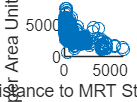

aux = ones(n,1); % primera columna de X.
X = [aux X]; % concatenamos ambas matrices obteniendo así X.
x1 = M(:,1); % extraemos los valores del primer regresor.
x2 = M(:,2); % extraemos los valores del segundo regresor.
y_mean = mean(y); % calculamos la media de y.

Xt = transpose(X); % hacemos la transpuesta de X.
XtX = Xt*X; % multiplicamos la transpuesta de X por X.
XtY = Xt*y; % multiplicamos la transpuesta de X por y. 
XtX1 = inv(XtX); % calculamos la inversa de XtX.
b = XtX1*XtY; % obtenemos los valores de b con el método de mínimos cuadrados.
y_aprox = X*b; % multiplicamos los valores de X por los coeficientes b.

scatter(x1,y) % Distribución datos x1-y
xlabel('Distance to MRT Station(m)')
ylabel('Price per Area Unit (EUR/m2)')

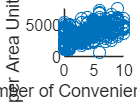

scatter(x2,y) % Distribución datos x2-y
xlabel('Number of Convenience Stores')
ylabel('Price per Area Unit (EUR/m2)')

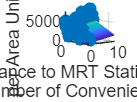


scatter3(x1,x2,y,'filled') 
hold on
x1fit = min(x1):100:max(x1);
x2fit = min(x2):10:max(x2);
[X1FIT,X2FIT] = meshgrid(x1fit,x2fit);
YFIT = b(1) + b(2)*X1FIT + b(3)*X2FIT;
mesh(X1FIT,X2FIT,YFIT)
xlabel('Distance to MRT Station(m)')
ylabel('Number of Convenience Stores')
zlabel('Price per Area Unit (EUR/m2)')
view(50,10)
hold off

# QUESTION 3

% write your code here code

v = n-k-1;

SS_REG = sum(power(y_aprox-y_mean,2)); % suma cuadrados modelo
SS_ERR = sum(power(y-y_aprox,2)); % suma cuadrados error
SS_TOT = SS_REG + SS_ERR; % suma cudrados total

MS_REG = SS_REG/k; % suma cuadrados modelo media
MS_ERR = SS_ERR/(n-k-1); % suma cuadrados error media

F = MS_REG/MS_ERR; % F value

R2 = SS_REG/SS_TOT; % Coeficiente de determinación

p_f = 1-fcdf(F,k,v); % p value de F test

# QUESTION 4

% write your code here
s2 = MS_ERR; % variancia mostral
VAR = s2*XtX1; % variancia 
t0 = b(1)/sqrt(VAR(1,1)); % t value b0
t1 = b(2)/sqrt(VAR(2,2)); % t value b1
t2 = b(3)/sqrt(VAR(3,3)); % t value b2

p0 = 2*(1-tcdf(t0,v)); % Compute p value for b0
p1 = 2*(1-tcdf(t1,v)); % Compute p value for b1
p2 = 2*(1-tcdf(t2,v)); % Compute p value for b2

